Locate KT2008.hmod, call **hans** in MATLAB to compile the script file.

hans KT2008

Parsing...
Symbolic parser failed. Switching to AD parser...ok!
Compiling dpopt_vfi
Building with 'MinGW64 Compiler (C++)'.
MEX completed successfully.


ans = struct with fields:
               parameters: {'beta'  'sigma'  'alpha'  'nu'  'delta'  'xi_max'  'a'  'w'  'z'  'd'}
                var_shock: 'e'
                var_state: 'k'
              var_pre_vfi: {1×0 cell}
               var_policy: {'ka'  'kc'}
                  var_aux: {'p'  'nd'  'kp'  'y'  'c'}
                  var_agg: 'C'
            var_agg_shock: 'z'
           var_agg_params: {'chi'  'delta'  'sigma'  'beta'}
           var_agg_assign: {'d'  'w'}
    var_agg_in_ind_params: {'d'  'w'  'z'}
            var_ind_in_eq: {'y'  'nd'  'kp'  'k'}

We first solve the calibration block.

tic;
cali_rslt = solve_cali;

Evaluating at var_agg: 0.4135, 2.32531, 
VFI converged (metric_v) 9.85215e-09, (metric_pol) 4.29862e-07 in 390 iterations
Range of k: 0, 3.68
Equilbirium residual: 0.000197203, -0.000149756, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   6.131594e-08   2.476205e-04
Evaluating at var_agg: 0.4136, 2.32531, 
VFI converged (metric_v) 9.64107e-09, (metric_pol) 2.48728e-07 in 227 iterations
Range of k: 0, 3.68
Equilbirium residual: 0.000959078, -0.000766295, 
Evaluating at var_agg: 0.4135, 2.32554, 
VFI converged (metric_v) 9.86429e-09, (metric_pol) 3.76106e-07 in 213 iterations
Range of k: 0, 3.68
Equilbirium residual: 0.000470949, -0.000404774, 
Evaluating at var_agg: 0.413464, 2.32538, 
VFI converged (metric_v) 9.81415e-09, (metric_pol) 7.01103e-08 in 216 iterations
Range of k: 0, 3.68
Equilbirium residual: 3.96032e-08, -1.34074e-09, 

             1              1   

toc;

Elapsed time is 1.464644 seconds.


cali_rslt.var_agg

ans = struct with fields:
      C: 0.4135
    chi: 2.3254
      z: 0
      w: 0.9615

We then solve the steady state, by passing in the calibrated parameters.

ss_rslt = solve_ss(cali_rslt);

Evaluating at var_agg: 0.413464, 
VFI result reused
Range of k: 0, 3.68
Equilbirium residual: 3.97218e-08, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   1.577820e-15   3.972178e-08
Evaluating at var_agg: 0.413464, 
VFI result reused
Range of k: 0, 3.68
Equilbirium residual: 3.97218e-08, 


Let's inspect the solved aggregate variables at the steady state

ss_rslt.var_agg

ans = struct with fields:
    C: 0.4135
    z: 0
    d: 0.9610
    w: 0.9615
    N: 0.3333

Let's inspect the policy functions. The probability for incuring the adjustment cost:

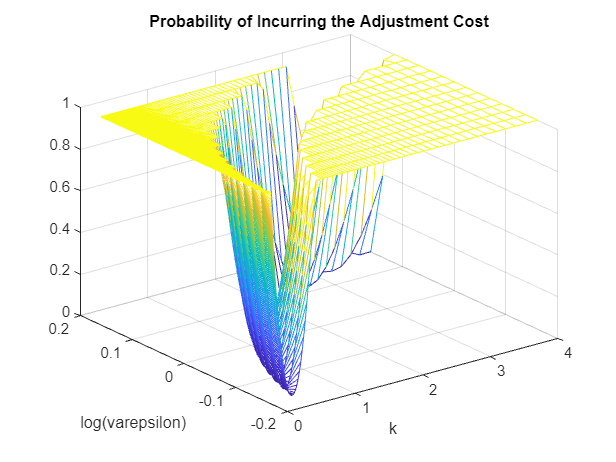

mesh(ss_rslt.vfi_rslt.var_state.k, ss_rslt.vfi_rslt.var_shock.e, ss_rslt.vfi_rslt.var_aux.p);
ylabel('log(varepsilon)');
xlabel('k');
title('Probability of Incurring the Adjustment Cost')

As shown, the investment decision exhibits an (S,s) rule: the adjustment cost is incurred when capital level is either too low or too high compared to the desired level.

The stationary distribution

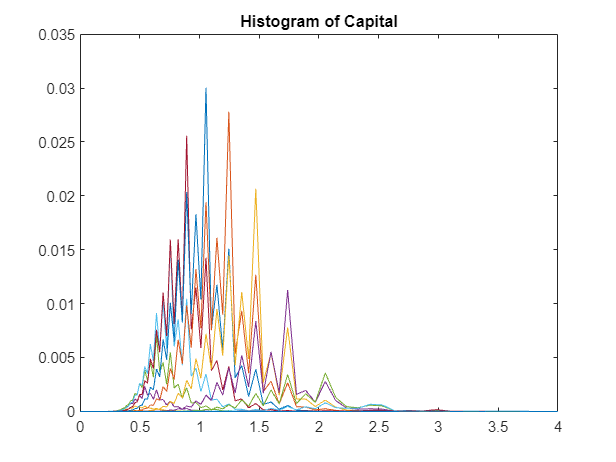

plot(ss_rslt.vfi_rslt.var_state.k,ss_rslt.dist); title('Histogram of Capital');

Note that the zig-zag shape of the histogram is a feature. One can replicate such patterns by increasing the number of capital grids in the code for solving steady states in Winberry (2018). 

We next generate a time series of aggregate productivity shock.

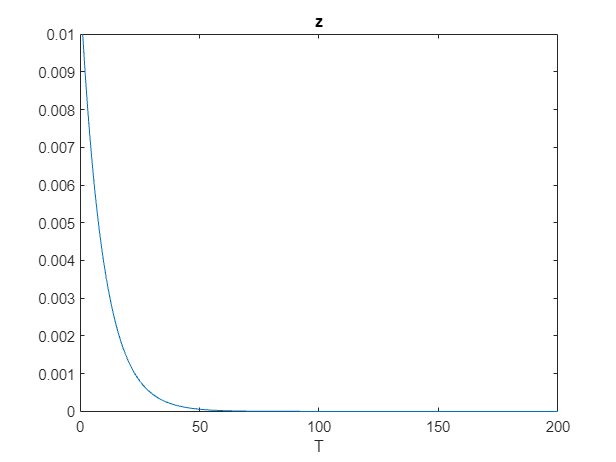

rho_z = 0.9;
size_z_shock = 0.01;
T = 200;
z_t = size_z_shock*rho_z.^[0:T-1];
plot(z_t); title('z'); xlabel('T')

We feed the aggregate shock into the model and solve the transition path.

Note solve_trans_nonlinear takes three arguments, the first for the initial steady state and the second for the final steady state.

options = struct;
options.z_t = z_t;
tic;
trans_rslt = solve_trans_nonlinear(ss_rslt,ss_rslt,options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   3.386038e-07   5.818968e-04

             1              1              2   2.281655e-09   4.776667e-05   5.418998e-05   1.000000e+00        Broyden


toc;

Elapsed time is 10.657985 seconds.


Let's inspect the transition path.

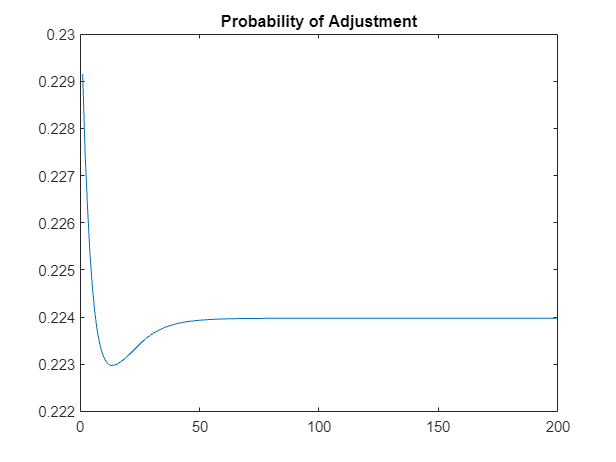

plot(trans_rslt.var_agg_t.p); title('Probability of Adjustment');

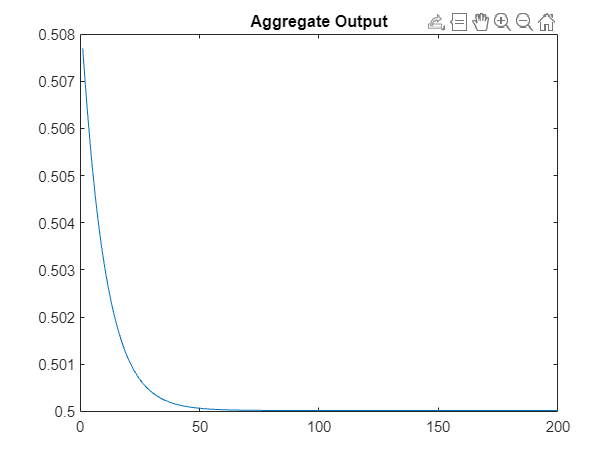

plot(trans_rslt.var_agg_t.y); title('Aggregate Output');

As shown, the probability of incurring the fixed adjustment cost rises after a positive productivity shock, showing that an important share of investment adjustment is at the extensive margin.

Does non-convex adjustment cost generate aggregate non-linearity?

Let's increase the size of the shock, and resolve the transition path.

options.z_t = 10*z_t;
trans_large_shock = solve_trans_nonlinear(ss_rslt,ss_rslt,options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   3.372703e-03   5.807498e-02

             1              1              2   1.824057e-04   1.350577e-02   5.670312e-03   1.000000e+00        Broyden

             2              1              3   3.383330e-06   1.839383e-03   4.916697e-04   1.000000e+00        Broyden

             3              1              4   9.411725e-08   3.067854e-04   2.803021e-05   1.000000e+00        Broyden

             4              1              5   1.220428e-10   1.104730e-05   3.834561e-06   1.000000e+00        Broyden


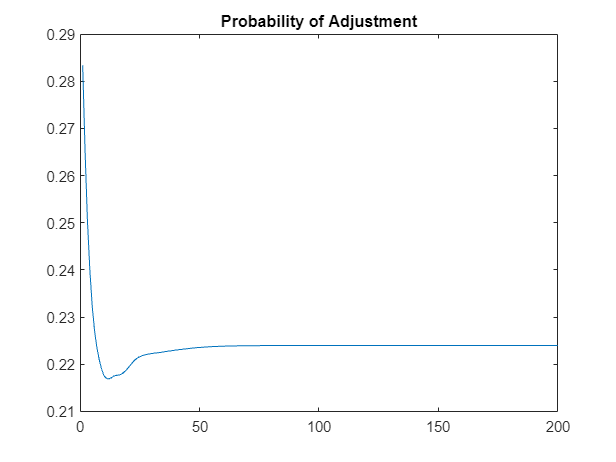

plot(trans_large_shock.var_agg_t.p); title('Probability of Adjustment');

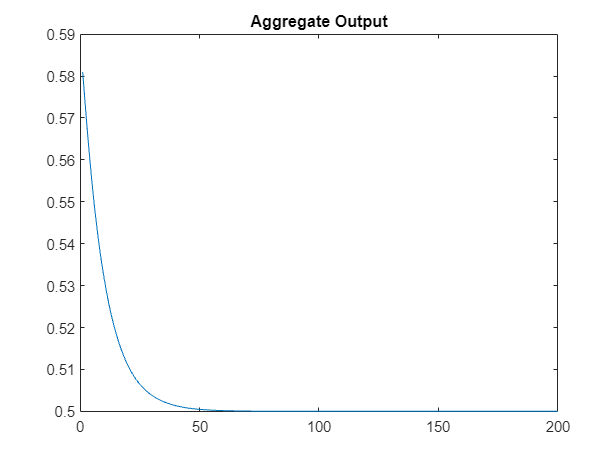

plot(trans_large_shock.var_agg_t.y); title('Aggregate Output');

As shown, increasing the size of the shock by 10 times leads to responses of endogenous variables to increase by roughly the same factor.

This shows that the model does not exhibit aggregate nonlinearity despite micro-level non-covex adjustment cost, echoing findings by Khan and Thomas (2008).